# Работа с веб-сервисами в MATLAB

Примеры получения данных из интернета напрямую в MATLAB

## Получение метеоданных

Разберем взаимодействие с сервисом погоды [OpenWeatherMap](https://openweathermap.org/) разными способами.

Прежде чем начать, нужно [зарегистрироваться](https://home.openweathermap.org/users/sign_up) на сайте и [получить](https://openweathermap.org/appid) API Key, который нужен для доступа к сервису. Впишите свой API Key ниже (в кавычках)

api_key = '...';

### Использование стандартных функций MATLAB

Порядок обращения к сервису описан на [сайте](https://openweathermap.org/api). Исопльзуем встроенные функции MATLAB, чтобы узнать текущую погоду в Москве

w = webread('https://api.openweathermap.org/data/2.5/weather', 'q', 'moscow,ru', 'units', 'metric', 'APPID', api_key)

w = struct with fields:
         coord: [1×1 struct]
       weather: [1×1 struct]
          base: 'stations'
          main: [1×1 struct]
    visibility: 10000
          wind: [1×1 struct]
        clouds: [1×1 struct]
            dt: 1.5383e+09
           sys: [1×1 struct]
            id: 524901
          name: 'Moscow'
           cod: 200


w.main

ans = struct with fields:
        temp: 7.2500
    pressure: 1020
    humidity: 70
    temp_min: 7
    temp_max: 8


### Использование библиотеки Req из MATLAB WEB API

Сначала нужно установить [MATLAB WEB API](https://www.mathworks.com/matlabcentral/fileexchange/68611). Это можно сделать двумя способами:

- [Скачайте](https://www.mathworks.com/matlabcentral/fileexchange/68611) **Toolbox** с File Exchange и установите

ИЛИ

- Выполните код:

Библиотека `Req` является ядром MATLAB WEB API, но может быть использована отдельно. Она позволяет эффективнее и удобнее работать с веб-запросами в MATLAB.

Узнаем текущую погоду в Москве с помощью библиотеки `Req`

% Создаем веб-запрос
req = WEB.API.Req('https://api.openweathermap.org/data/2.5/weather');
% Добавляем параметры запроса
req.addquery('q', 'moscow,ru'); % задаем город
req.addquery('units', 'metric'); % задаем единицы измерения
req.addquery('APPID', api_key);  % добавляем API Key
% Совершаем GET-запрос, получаем данные
w = get(req)

w = struct with fields:
         coord: [1×1 struct]
       weather: [1×1 struct]
          base: 'stations'
          main: [1×1 struct]
    visibility: 10000
          wind: [1×1 struct]
        clouds: [1×1 struct]
            dt: 1.5383e+09
           sys: [1×1 struct]
            id: 524901
          name: 'Moscow'
           cod: 200


w.main

ans = struct with fields:
        temp: 6.7500
    pressure: 1020
    humidity: 75
    temp_min: 6
    temp_max: 8


### Использование MATLAB WEB API

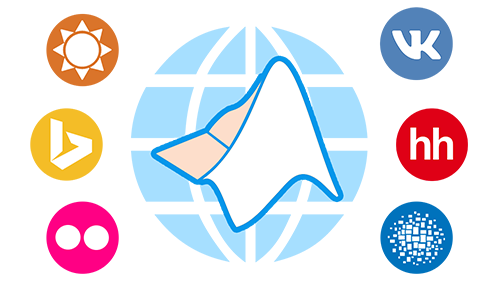

На самом деле работа с сервисом OpenWeatherMap уже частично реализована в MATLAB WEB API в виде отдельного **OpenWeatherMap API. **Использование API позволяет не думать о составлении запросов. В нашем распоряжении высокоуровневые функции, которые просто делают свою работу.

Узнаем текущую погоду в Москве с помощью MATLAB OpenWeatherMap API и визуализируем её

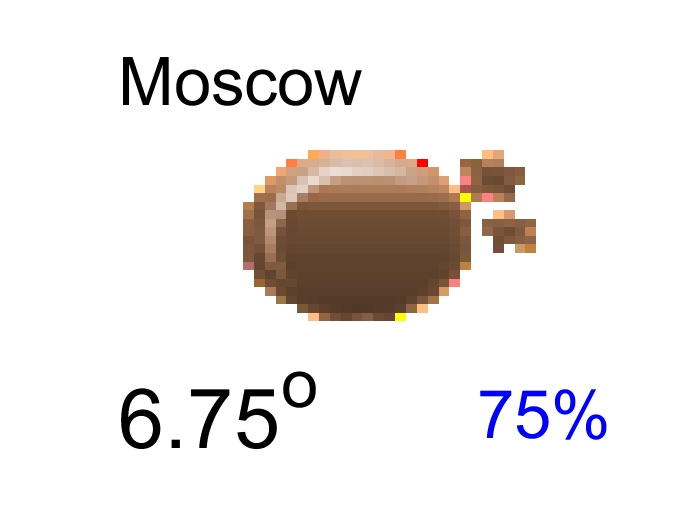

w = struct with fields:
         coord: [1×1 struct]
       weather: [1×1 struct]
          base: 'stations'
          main: [1×1 struct]
    visibility: 10000
          wind: [1×1 struct]
        clouds: [1×1 struct]
            dt: 1.5383e+09
           sys: [1×1 struct]
            id: 524901
          name: 'Moscow'
           cod: 200


owm = WEB.OpenWeatherMap(api_key);
w = owm.current('q', 'moscow,ru', 'units', 'metric', 'show', true)

Узнаем прогноз погоды в Москве на 5 дней

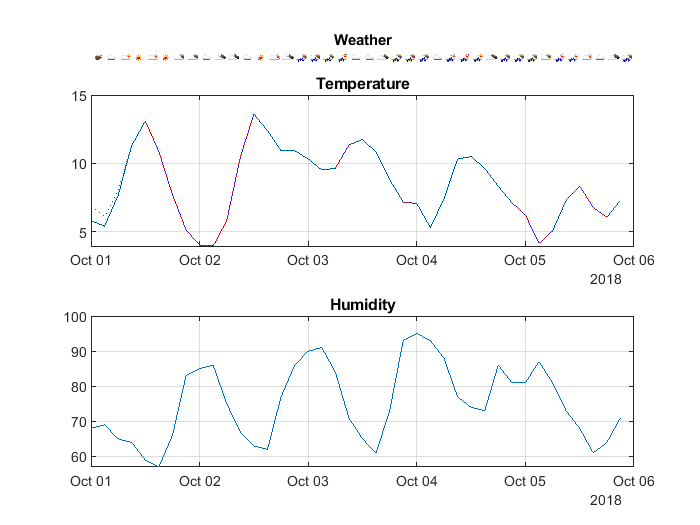

w = struct with fields:
        cod: '200'
    message: 0.0322
        cnt: 40
       list: {40×1 cell}
       city: [1×1 struct]


w = owm.forecast('q', 'moscow,ru', 'units', 'metric', 'show', true)

## Еще примеры MATLAB WEB API

[Полный список](https://github.com/ETMC-Exponenta/MATLAB-WEB-API/blob/master/%2BWEB/README.md) поддерживаемых сервисов

### Bing Maps - сервис картографии

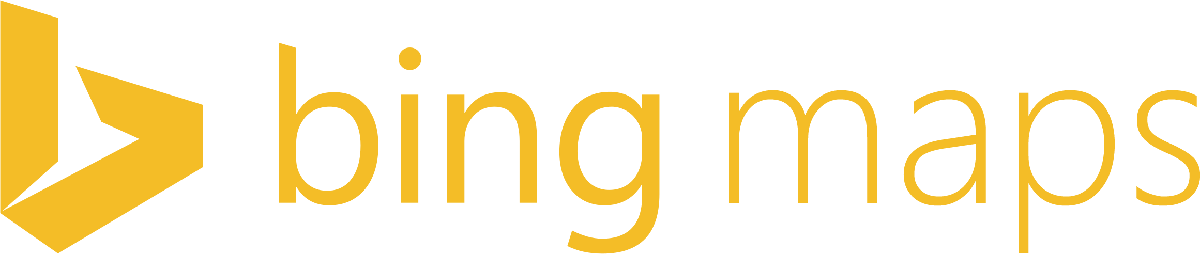

Для работы с Bing Maps нужно [получить ключ доступа](https://msdn.microsoft.com/library/ff428642.aspx). Впишите его ниже

api_key = '...';

Найдем Москву, отобразим результаты на карте

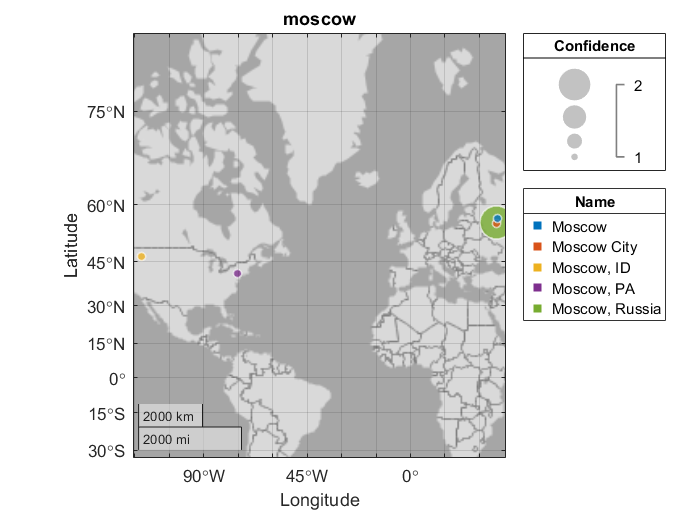

res = 5×8 table
        bbox              name             point          address       confidence       entityType       geocodePoints    matchCodes 
    ____________    ________________    ____________    ____________    __________    ________________    _____________    ___________

    [4×1 double]    'Moscow, Russia'    [1x1 struct]    [1×1 struct]     'Medium'     'PopulatedPlace'    [1x1 struct]     'Ambiguous'
    [4×1 double]    'Moscow City'       [1x1 struct]    [1×1 struct]     'Low'        'AdminDivision1'    [1x1 struct]     'Ambiguous'
    [4×1 double]    'Moscow'            [1x1 struct]    [1×1 struct]     'Low'        'AdminDivision1'    [1x1 struct]     'Ambiguous'
    [4×1 double]    'Moscow, ID'    

bm = WEB.BingMaps(api_key);
res = bm.location_findByQuery('moscow', 'maxResults', 5, 'plot', true)

Получим карту Москвы

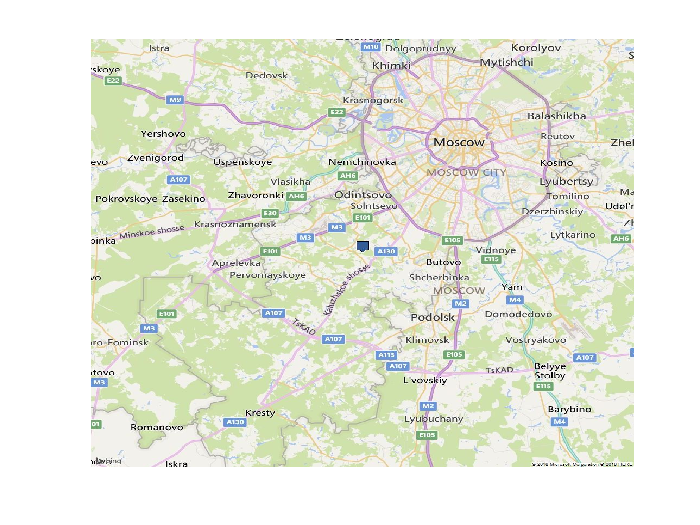

bm.imagery_staticMap('Road', 'moscow, city', 'show', 1, 'mapSize', [1000,1000], 'dpi', 'large');

Получим снимок из космоса по координатам

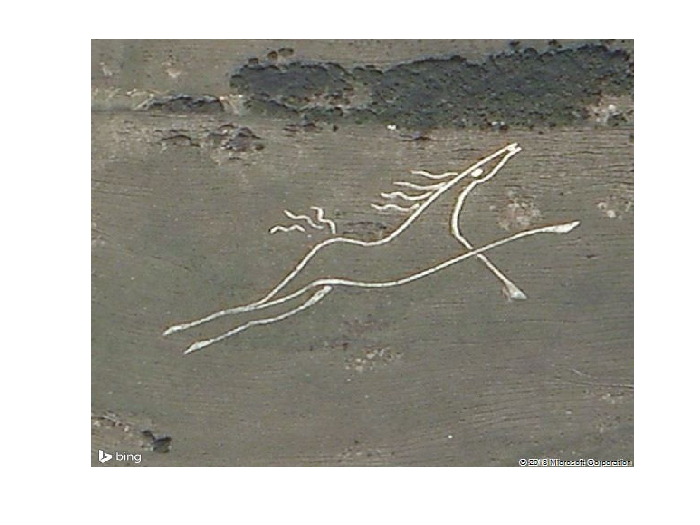

bm.imagery_staticMap('aerial', [51.1011 1.1395], 'zoomLevel', 19, 'show', 1, 'mapSize', [600, 600]);

### Flickr - фотохостинг

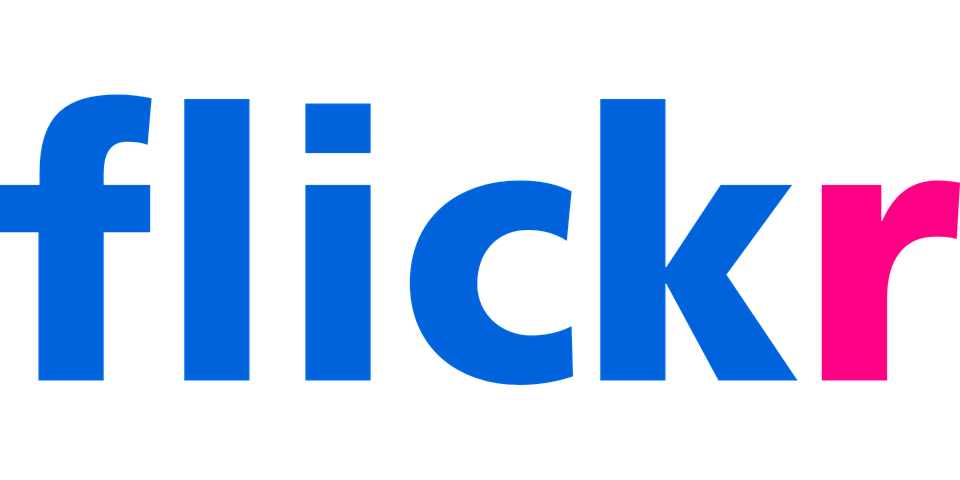

Чтобы работать с Flickr, сначала нужно зарегистрироваться на [сайте](https://www.flickr.com/services/api/).

*Совет: при регистрации используйте почту иностранных сервисов (например, gmail).*

Затем нужно [создать на сайте приложение](https://www.flickr.com/services/api/keys/) и получить ключи. Впишите их ниже

app_key = '...';
app_secret = '...';

Найдем фотографии котиков и выведем одну из них на экран

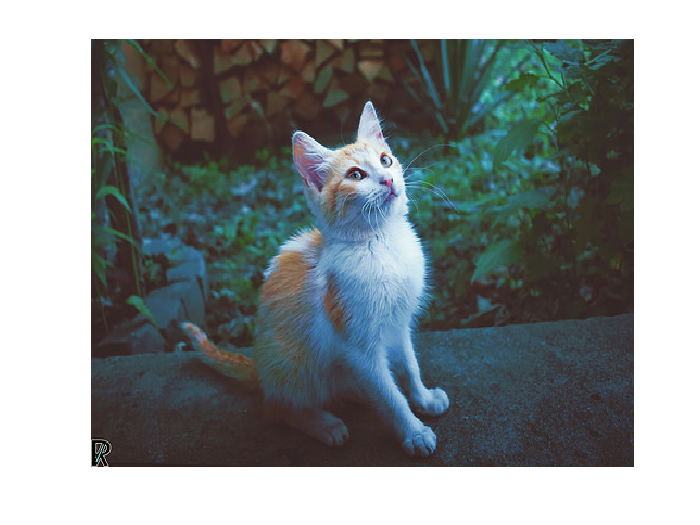

fl = WEB.Flickr(app_key, app_secret);
cats = fl.photos_search('text', 'kitty', 'tags', 'cat');
photo = fl.get_photo(cats.photo.id{1}, 'size', 'medium', 'show', 1);

### VK - социальная сеть

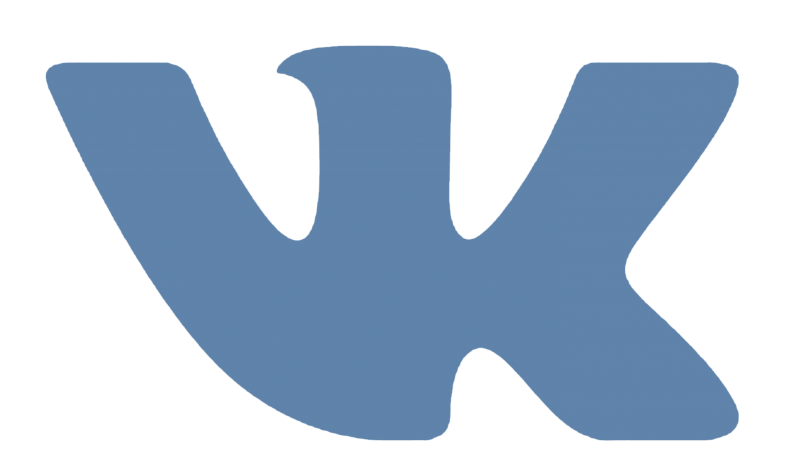

Для работы с VK API нужно [зарегистрировать свое приложение](https://vk.com/dev/first_guide?f=2.%20%D0%A0%D0%B5%D0%B3%D0%B8%D1%81%D1%82%D1%80%D0%B0%D1%86%D0%B8%D1%8F%20%D0%BF%D1%80%D0%B8%D0%BB%D0%BE%D0%B6%D0%B5%D0%BD%D0%B8%D1%8F). Укажите **идентификатор** вашего приложения ниже

client_id = '...';

Подключимся к VK и авторизуемся

vk = WEB.VK(client_id, 'all');
vk.login('implicit');

Список подписчиков Экспоненты

res = vk.groups_getMembers('41030489', 'fields', 'city,sex', 'getAll', 1);
res(:, {'first_name', 'sex', 'city'})

ans = 2477×3 table
    first_name     sex        city    
    ___________    ___    ____________

    'Тимофей'       2     [1×1 struct]
    'Максим'        2     [1×1 struct]
    'Ксения'        1     [1×1 struct]
    'Денис'         2     [1×1 struct]
    'Егор'          2     [1×1 struct]
    'Олег'          2     [1×1 struct]
    'Юрий'          2     [1×1 struct]
    'Даир'          2     [1×1 struct]
    'Михаил'        2     [1×1 struct]
    'Евгений'       2     [1×1 struct]
    'Stacey'        1     ''          
    'Данила'        2     [1×1 struct]
    'Станислав'     2     [1×1 struct]
    'Донат'         2     [1×1 struct]
    'Григорий'      2     [1×1 struct]
    'Вадим'         2     ''          


Получите список своих друзей

my_id = '852372'; % введите свой числовой ID
res = vk.friends_get(my_id, 'fields', 'nickname');
res(:, {'first_name', 'online'})

ans = 187×2 table
     first_name     online
    ____________    ______

    'Владимир'        0   
    'Мария'           0   
    'Сергей'          0   
    'Константин'      0   
    'Павел'           0   
    'Ирина'           0   
    'Антон'           0   
    'Игорь'           0   
    'Marina'          0   
    'Алёна'           0   
    'Алла'            0   
    'Ириша'           0   
    'Евгения'         0   
    'Максим'          0   
    'Таня'            0   
    'Георгий'         0   


## **Присоединяйтесь к созданию MATLAB WEB API!**

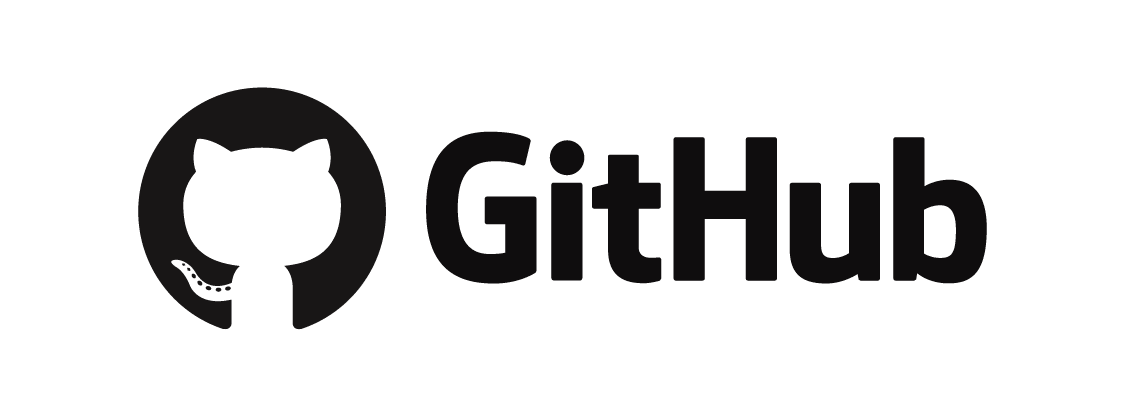

[Проект на GitHub](https://github.com/ETMC-Exponenta/MATLAB-WEB-API)

[Как присоединиться](https://git-scm.com/book/ru/v2/GitHub-%D0%92%D0%BD%D0%B5%D1%81%D0%B5%D0%BD%D0%B8%D0%B5-%D1%81%D0%BE%D0%B1%D1%81%D1%82%D0%B2%D0%B5%D0%BD%D0%BD%D0%BE%D0%B3%D0%BE-%D0%B2%D0%BA%D0%BB%D0%B0%D0%B4%D0%B0-%D0%B2-%D0%BF%D1%80%D0%BE%D0%B5%D0%BA%D1%82%D1%8B)

*Pavel Roslovets, *[*ETMC Exponenta*](https://exponenta.ru/)* © 2018*